Práctica 7

%parte del modelo de la planta siguiente:

A=[0 1; 0 -9.091]

A =          0    1.0000
         0   -9.0910


B=[0; 25.93]

B =          0
   25.9300


C=[4.95 0; 0 0.869]

C =     4.9500         0
         0    0.8690


D=0

D = 0

sys=ss(A,B,C,D);
G=tf(sys)

G =
 
  From input to output...
           128.4
   1:  -------------
       s^2 + 9.091 s
 
         22.53
   2:  ---------
       s + 9.091
 
Continuous-time transfer function.



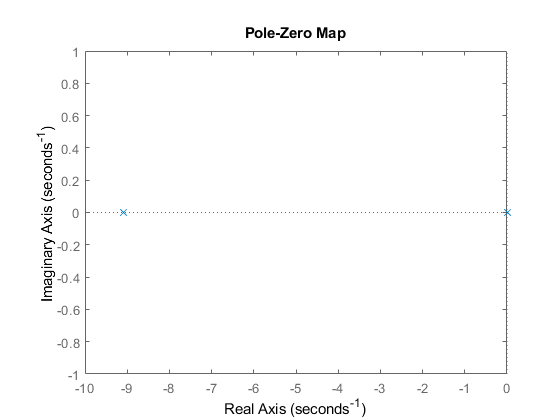

pzmap(G)

rank(ctrb(A,B))

ans = 2

%el polo en bucle abierto esta cerca de -6.25
%el polo deseado estara cerca de este valor

Obtención del vector de ganancias de realimentación

T=0.001;
e=0.9455;
wn=3.9/(0.08*e);
Pb=[1 2*e*wn wn^2];
Ps=roots(Pb)

Ps =  -48.7500 +16.7891i
 -48.7500 -16.7891i


Pz=exp(Ps*T)

Pz =    0.9523 + 0.0160i
   0.9523 - 0.0160i


sysd=c2d(sys,T,'zoh');

H=acker(sysd.A,sysd.B,Pz)

H =    98.1070    3.2973


Control integral mediante variables de integración

% % En caso de añadir una nueva variable de estados porque solo considero uno de las dos salidas del sistema 

%1

Aa=[sysd.A(1,1) sysd.A(1,2) 0; sysd.A(2,1) sysd.A(2,2) 0; -sysd.C(1,1) -sysd.C(1,2) 1]

Aa =     1.0000    0.0010         0
         0    0.9910         0
   -4.9500         0    1.0000


Ba=[sysd.B(1,1);sysd.B(2,1);0];

%2
Pba=conv(Pb,[1 73.125]) %  añado el polo que me piden

Pba = 	1.0e+05 *

    0.0000    0.0017    0.0979    1.9440


Ps=roots(Pba)

Ps =  -73.1250 + 0.0000i
 -48.7500 +16.7891i
 -48.7500 -16.7891i


Pz=exp(Ps*T)

Pz =    0.9295 + 0.0000i
   0.9523 + 0.0160i
   0.9523 - 0.0160i



%3
Ha=acker(Aa,Ba,Pz)

Ha =   355.3415    5.9003   -1.3976



%prueba
% Ca=[0.2022 0 0; 0 1.22 0;0 0 0]
% D=0
% sysp=ss(Aa,Ba,Ca,D);
% Gp=tf(sys)
% Hp=[Ha(1,1) Ha(1,2) Ha(1,3); 0 0 0]
% step(feedback(sysp,Hp,-1))


% En caso de añadir dos nuevas variables estados porque le sistema tiene
%dos salidas.

% %1
% Aa=[sysd.A(1,1) sysd.A(1,2) 0 0; sysd.A(2,1) sysd.A(2,2) 0 0; -sysd.C(1,1) -sysd.C(1,2) 1 0;-sysd.C(2,1) -sysd.C(2,2) 0 1]
% Ba=[sysd.B(1,1);sysd.B(2,1);0;0];
% Ca=[sysd.C(1,1) sysd.C(1,2) 0 0;sysd.C(2,1) sysd.C(2,2) 0 0];
% 
% 
% %2
% Pba=conv(Pb,[70 73.125 ]) %  añado el polo que me piden
% Pbaa=conv(Pba,[1 96]) %añado otro polo muy alejado para conseguir obtener H
% Psa=roots(Pbaa)
% Pza=exp(Psa*T)
% 
% %3-- > he tenido que añadir un polo en cero para conseguir que Pza tenga la
% %misma dimension que Aa.
% Ha=acker(Aa,Ba,Pza)

### práctica 7. cogiendo un polinomio que considero mas adecuado  ya que me da una H ma pequeña.

% intoento colocar los polos deseados lo mas cercano posible a los polos de
% buble abierto y obteniendo un tiempo de establecimiento no muy grande.
% los coloco en -9. obtengo un tiempo de establecimiento entorno a 0.5, 
T=0.001;
% ep=0.99;
% wn=9.013;
% Pd=[1 2*ep*wn wn^2];
Pd=[1 20.945 527.566]

Pd =     1.0000   20.9450  527.5660


Ps=roots(Pd)

Ps =  -10.4725 +20.4424i
 -10.4725 -20.4424i


Pz=exp(Ps*T)

Pz =    0.9894 + 0.0202i
   0.9894 - 0.0202i


sysd=c2d(sys,T,'zoh');

H=acker(sysd.A,sysd.B,Pz)

H =    20.2250    0.4625



%1

Aa=[sysd.A(1,1) sysd.A(1,2) 0; sysd.A(2,1) sysd.A(2,2) 0; -sysd.C(1,1) -sysd.C(1,2) 1]

Aa =     1.0000    0.0010         0
         0    0.9910         0
   -4.9500         0    1.0000


Ba=[sysd.B(1,1);sysd.B(2,1);0];

% el nuevo sisteema amplidado que puedo servir de observador tambien 

Ca=[sysd.C(1,1) sysd.C(1,2) 0;sysd.C(2,1) sysd.C(2,2) 0; 0 0 0];
Da=[0;0;0];
sysa=ss(Aa,Ba,Ca,Da)

sysa =
 
  A = 
              x1         x2         x3
   x1          1  0.0009955          0
   x2          0      0.991          0
   x3      -4.95          0          1
 
  B = 
              u1
   x1  1.293e-05
   x2    0.02581
   x3          0
 
  C = 
          x1     x2     x3
   y1   4.95      0      0
   y2      0  0.869      0
   y3      0      0      0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



aa=Aa';
cc=Ca';


%2
Pba=conv(Pd,[1 15.7]) %  añado el polo que me piden

Pba = 	1.0e+03 *

    0.0010    0.0366    0.8564    8.2828


Ps=roots(Pba)

Ps =  -10.4725 +20.4424i
 -10.4725 -20.4424i
 -15.7000 + 0.0000i


Pz=exp(Ps*T)

Pz =    0.9894 + 0.0202i
   0.9894 - 0.0202i
   0.9844 + 0.0000i



%3
Ha=acker(Aa,Ba,Pz)

Ha =    32.8907    1.0596   -0.0636


L=acker(aa,cc,Pz)

Error using acker (line 31)
System must be single input

% no se si es necesario calculllar la r para obte

% diseño del pid

G1=tf([128.4],[1 9.091 0])
pidtool(G1)

  Kp + Ki * 1/s

  with Kp = 0.674, Ki = 0.08